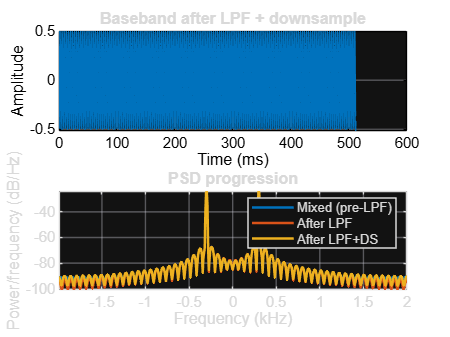

close all; clear; clc;

% Parameters
fs     = 8000; Ts = 1/fs; N = 4096; t = (0:N-1)*Ts;
f_sig  = 1800;                 % Hz
f_LO   = 1500;                 % Hz
f_diff = abs(f_sig - f_LO);   % 300 Hz
f_sum  = f_sig + f_LO;        % 3300 Hz

% Signals
x     = cos(2*pi*f_sig*t);
lo    = cos(2*pi*f_LO*t);
y_mix = x .* lo;

% LPF -> Decimate
Fc   = 1000;                        % Hz
y_lp = lowpass(y_mix, Fc, fs);
M    = 2;                           % 8 kHz -> 4 kHz
fs_y = fs/M;
y_dec = downsample(y_lp, M);
t_ds  = (0:numel(y_dec)-1).' / fs_y;

% time + PSD
figure;
subplot(2,1,1);
ns = min(5000, numel(y_dec));
plot(t_ds(1:ns)*1e3, y_dec(1:ns), 'LineWidth', 1); grid on;
xlabel('Time (ms)'); ylabel('Amplitude');
title('Baseband after LPF + downsample');

subplot(2,1,2);
pwelch(y_mix, [], [], [], fs,   'centered'); hold on;
pwelch(y_lp,  [], [], [], fs,   'centered');
pwelch(y_dec, [], [], [], fs_y, 'centered');
legend('Mixed (pre-LPF)','After LPF','After LPF+DS');
title('PSD progression'); grid on;


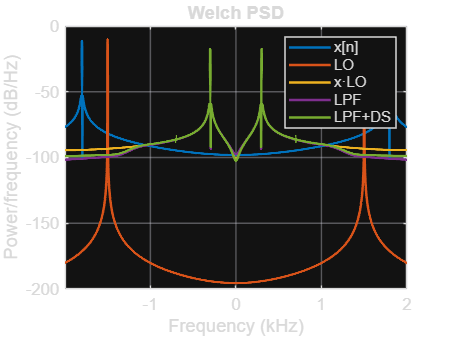

% Inspect spectrum
figure;
pwelch(x,     4096, 2048, 4096, fs,   'centered'); hold on;
pwelch(lo,    4096, 2048, 4096, fs,   'centered');
pwelch(y_mix, 4096, 2048, 4096, fs,   'centered');
pwelch(y_lp,  4096, 2048, 4096, fs,   'centered');
pwelch(y_dec, 2048, 1024, 2048, fs_y, 'centered');
legend('x[n]','LO','x·LO','LPF','LPF+DS');
grid on; title('Welch PSD');


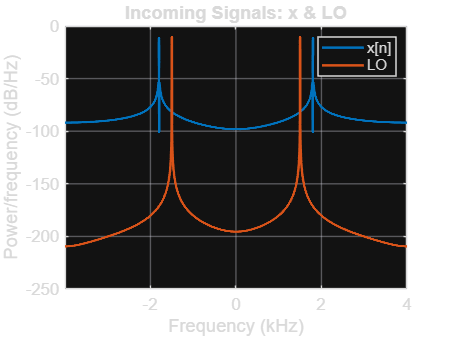

% x & LO
figure;
pwelch(x,  4096, 2048, 4096, fs, 'centered'); hold on;
pwelch(lo, 4096, 2048, 4096, fs, 'centered');
legend('x[n]','LO'); grid on; title('Incoming Signals: x & LO');


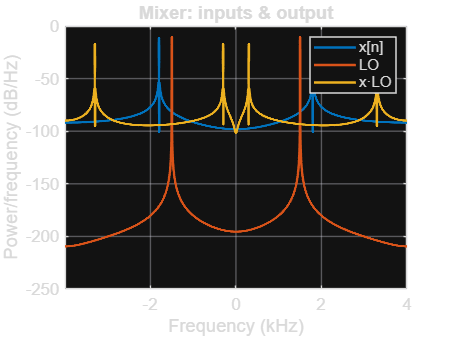

% Mixer stage
figure;
pwelch(x,     4096, 2048, 4096, fs, 'centered'); hold on;
pwelch(lo,    4096, 2048, 4096, fs, 'centered');
pwelch(y_mix, 4096, 2048, 4096, fs, 'centered');
legend('x[n]','LO','x·LO'); grid on; title('Mixer: inputs & output');


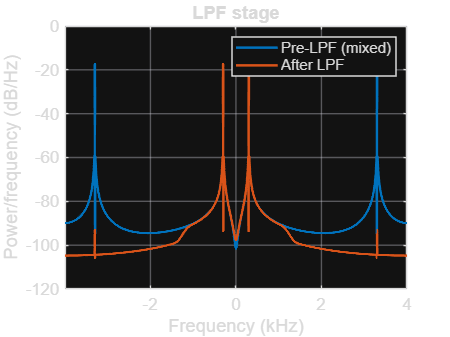

% LPF stage
figure;
pwelch(y_mix, 4096, 2048, 4096, fs, 'centered'); hold on;
pwelch(y_lp,  4096, 2048, 4096, fs, 'centered');
legend('Pre-LPF (mixed)','After LPF'); grid on; title('LPF stage');


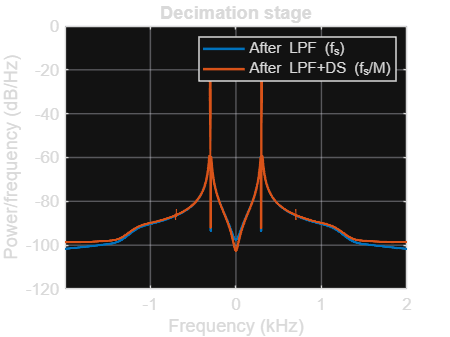

% Decimation stage
figure;
pwelch(y_lp,  4096, 2048, 4096, fs,   'centered'); hold on;
pwelch(y_dec, 2048, 1024, 2048, fs_y, 'centered');
legend('After LPF (f_s)','After LPF+DS (f_s/M)'); grid on; title('Decimation stage');